https://www.mathworks.com/help/symbolic/solve-differential-equation-numerically-1.html

syms y(t)
[V] = odeToVectorField(diff(y, 2) == (1 - y^2)*diff(y) - y)

$$V = \left(\begin{array}{c} Y_{2}\\ -\left({Y_{1}}^{2}-1\right)\,Y_{2}-Y_{1} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-(Y(1).^2-1.0).*Y(2)-Y(1)]


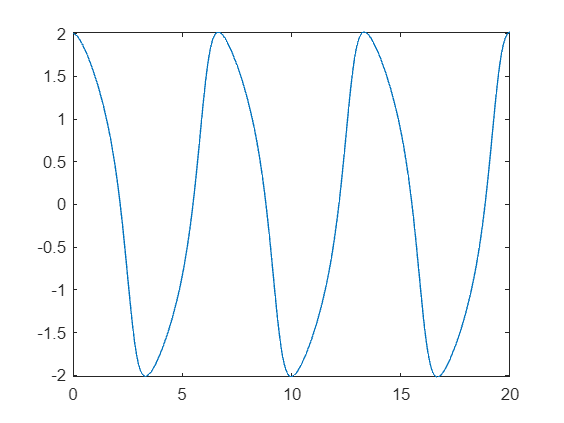

sol = ode45(M,[0 20],[2 0]);
fplot(@(x)deval(sol,x,1), [0, 20])

applying classic spring damper model

syms y(t)
%constants
k = 1; %spring
c = 1; %damper
m = 1; %mass
[V] = odeToVectorField(-m*diff(y, 2) == c*diff(y) + k*y)

$$V = \left(\begin{array}{c} Y_{2}\\ -Y_{1}-Y_{2} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)-Y(2)]


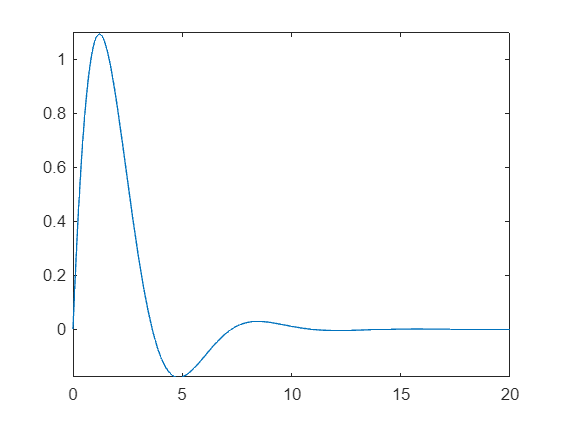

sol = ode45(M,[0 20],[0 2]);
fplot(@(x)deval(sol,x,1), [0, 20])

confirm by solving mathematically by hand

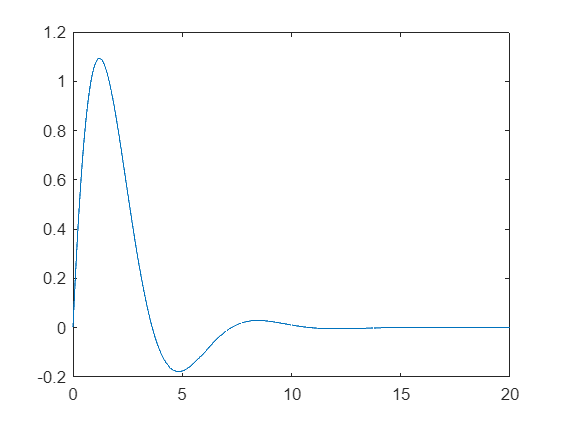

x = linspace(0,20,10000);
y = (4/sqrt(3))*exp(-1/2.*x).*sin(x.*sqrt(3)/2);
plot(x,y)

2 DOF spring sys (https://www.mathworks.com/help/symbolic/solve-a-system-of-differential-equations.html#SolveASystemOfDifferentialEquationsExample-2)

m = 1;
k = 2; %why are these not used????
syms x(t) y(t)
A = [-4 2; 2 -2];
Y = [x; y];
odes = diff(Y,2) == A*Y

$$odes(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=2\,y\left(t\right)-4\,x\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=2\,x\left(t\right)-2\,y\left(t\right) \end{array}\right)$$

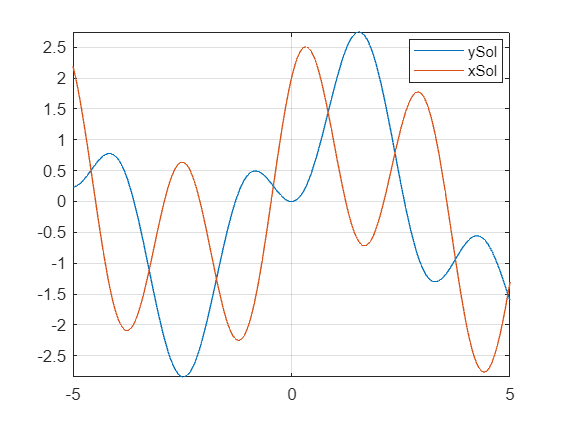

D = diff(Y);
C = [Y(0) == [2;0;],D(0) == [3;0]];
[xSol(t),ySol(t)] = dsolve(odes,C);
xSol(t) = simplify(xSol(t));
ySol(t) = simplify(ySol(t));
clf
fplot(ySol)
hold on
fplot(xSol)
grid on
legend('ySol','xSol','Location','best')

confirm by graphing system of first order ODEs 

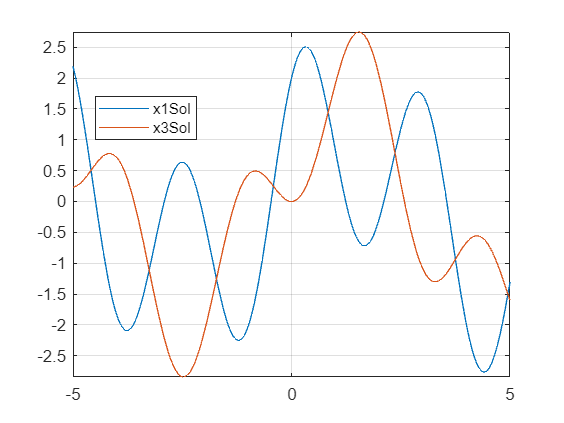

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -4 0 2 0; 0 0 0 1; 2 0 -2 0];
Y = [x1; x2; x3; x4];
odes = diff(Y) == A*Y;
C = [Y(0) == [2;3;0;0;]];
[x1Sol(t),x2Sol(t),x3Sol(t),x4Sol(t)] = dsolve(odes,C);
x1Sol(t) = simplify(x1Sol(t));
x3Sol(t) = simplify(x3Sol(t));
clf
fplot(x1Sol)
hold on
fplot(x3Sol)
grid on
legend('x1Sol','x3Sol','Location','best')

2dof mass spring damper system (solved numerically) assum. identical mass and constants

clf
hold on
m = 1;
k = 1; 
c = 2;
syms x(t) y(t)
A = [-(2*k/m) k/m; k/m -k/m];
B = [-2*c/m c/m; c/m -c/m];
Y = [x; y];
[V] = odeToVectorField(diff(Y,2) == A*Y + B*diff(Y))

$$V = \left(\begin{array}{c} Y_{2}\\ Y_{3}-2\,Y_{2}-Y_{1}+2\,Y_{4}\\ Y_{4}\\ Y_{1}+2\,Y_{2}-2\,Y_{3}-4\,Y_{4} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)-Y(2).*2.0+Y(3)+Y(4).*2.0;Y(4);Y(1)+Y(2).*2.0-Y(3).*2.0-Y(4).*4.0]



timeSpan = [0 20]; % Interval
stepSize = 0.01; % Smaller step size for more time points
timeGrid = timeSpan(1):stepSize:timeSpan(2); % Create a finer time grid

%sol = ode45(M,[0 20],[1 0 0 0])
sol = ode45(M,timeGrid,[1 0 0 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 2.0095e-04 0.0012 0.0062 0.0313 0.1096 0.2173 0.3621 0.5387 0.7387 0.9678 1.2266 1.5141 1.8091 2.2379 2.8305 3.6579 4.3981 5.1383 5.8132 6.3619 6.8796 7.5936 8.5474 9.1917 9.8360 10.5900 11.3689 12.0296 12.5691 13.0950 13.7067 14.4912 … ]
          y: [4×41 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


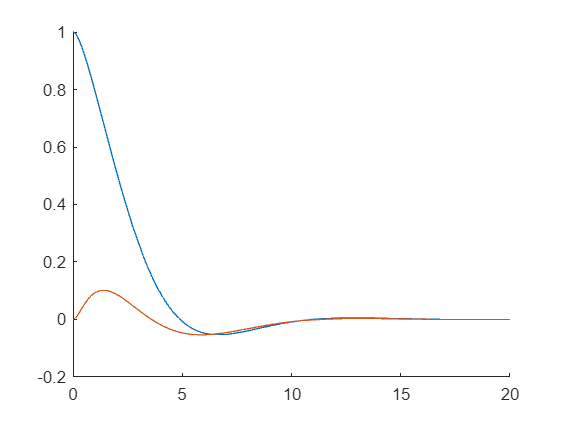


fplot(@(x)deval(sol,x,1), [0, 20])
fplot(@(x)deval(sol,x,3), [0, 20])


% Extract time points and solution values
timePoints = sol.x;
solutionValues = deval(sol, timePoints, 1:4) % Assuming the solution has 4 components

solutionValues =     1.0000    1.0000    1.0000    1.0000    0.9995    0.9948    0.9819    0.9566    0.9180    0.8681    0.8060    0.7326    0.6495    0.5648    0.4470    0.3013    0.1415    0.0439   -0.0155   -0.0433   -0.0522   -0.0528   -0.0458   -0.0305   -0.0199   -0.0109   -0.0029    0.0023    0.0046    0.0053    0.0054    0.0048    0.0037    0.0023    0.0014    0.0007    0.0001   -0.0003   -0.0004   -0.0004   -0.0004
         0   -0.0002   -0.0012   -0.0062   -0.0295   -0.0890   -0.1472   -0.1979   -0.2357   -0.2614   -0.2784   -0.2878   -0.2893   -0.2833   -0.2645   -0.2253   -0.1604   -0.1045   -0.0579   -0.0260   -0.0075    0.0045    0.0138    0.0170    0.0155    0.0125    0.0086    0.0048    0.0022    0.0007   -0.0004   -0.0012   -0.0016   -0.0015   -0.0013   -0.0010   -0.0006   -0.0003   -0.0001    0.0000    0.0001
         0    0.0000    0.0000    0.0000    0.0005    0.0048    0.0156    0.0334    0.0548    0.0749    0.0907    0.0997    0.1007    0.0941    0.0757    0.0423 


% Prepare data for export
data = [timePoints', solutionValues(1,:)', solutionValues(3,:)']; % Columns for t, x, y

% Export to CSV
filename = 'solution_data_damping.csv';
writematrix(data, filename);

% Display message
disp(['Data exported to ', filename]);

Data exported to solution_data_damping.csv


manual simplify to first order (keep in mind that the entries switched order in symbolic vector V)

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -2*k/m -c*2/m k/m c/m; 0 0 0 1; k/m c/m -k/m -c/m];
Y = [x1; x2; x3; x4];
clf
hold on
[V] = odeToVectorField(diff(Y) == A*Y )

$$V = \left(\begin{array}{c} Y_{3}-2\,Y_{2}-4\,Y_{1}+2\,Y_{4}\\ Y_{1}\\ Y_{4}\\ 2\,Y_{1}+Y_{2}-Y_{3}-2\,Y_{4} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(1).*-4.0-Y(2).*2.0+Y(3)+Y(4).*2.0;Y(1);Y(4);Y(1).*2.0+Y(2)-Y(3)-Y(4).*2.0]


sol = ode45(M,[0 20],[0 1 0 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 1.0048e-04 6.0285e-04 0.0031 0.0157 0.0785 0.1730 0.3041 0.4731 0.6628 0.8815 1.1294 1.4071 1.7054 2.0759 2.6113 3.3560 4.3032 4.8402 5.3771 6.0839 6.8825 7.4207 7.9588 8.5181 9.3532 10.3764 10.8797 11.3831 12.0928 12.9700 13.5768 … ]
          y: [4×42 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


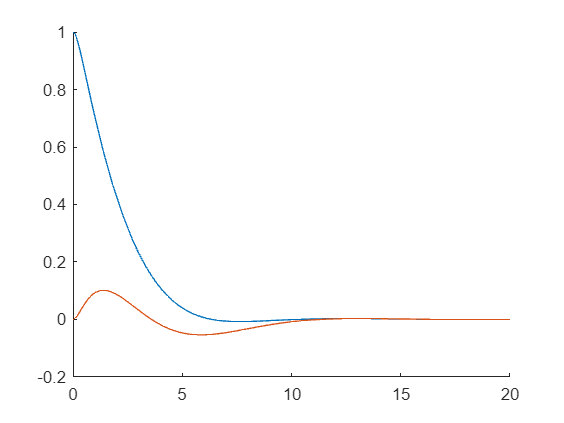

fplot(@(x)deval(sol,x,2), [0, 20])
fplot(@(x)deval(sol,x,3), [0, 20])